clear;
fileList = dir("C:\Users\piyorin\dev\AnalyzeHoof\new3dData\*.mat")

fileList = フィールドをもつ 61×1 の struct 配列:
    name
    folder
    date
    bytes
    isdir
    datenum


% fileList = dir("./new3dData/*.mat");

length(fileList)

ans =     61


numArrays = length(fileList); % ファイルの数
data = cell(numArrays,1); % 配列事前確保

for n = 1:length(fileList)
    chr = fileList(n).name;
    data{n} = chr;
    d(n, 1) = string(chr);
    lm = load(chr);
end


% 
% file = uigetfile('*.mat');

file = d(7);

m = load(file);
ptCloud = m.nPoint;

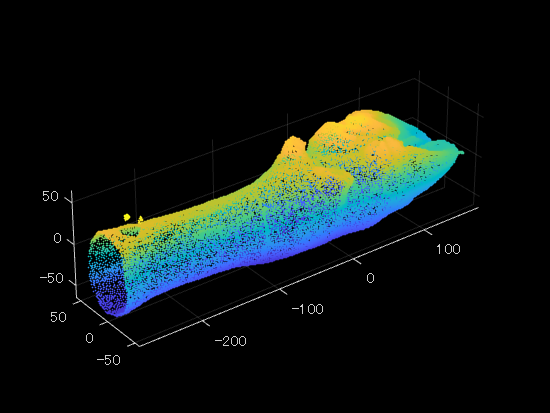

figure;
pcshow(ptCloud, AxesVisibility="on");

t = 1;
axIdx = 1;
[PosData, PointSet] = sliceModel(ptCloud, t, axIdx);

DataSize = length(PosData);
ConvArea = zeros(DataSize, 3);
rectangleArea = zeros(DataSize, 3);
FitCircleRho = zeros(DataSize, 3);

center = mean(PosData);


index = PosData>= center;
plusSectionPos = PosData(index);
plusSectionPt = PointSet(index);


for i = 1:DataSize
    pos = PosData(i);
    point = PointSet(i);
    pt = point.Location;
    yli = point.YLimits;
    zli = point.ZLimits;
    proJ = pt(:, [2 3]);
    ymax = min(proJ(:,1));

    [thetaSorted, rhoSorted] = sortPointOnPolar(proJ);
    [x, y] = pol2cart(thetaSorted, rhoSorted);
    sortSet = [x y];

    % 凸包断面積
    try
        [k, av] = convhull(sortSet);
        sortSetK = [sortSet(k, 1) sortSet(k, 2)];
        ConvArea(i,1) =pos;
        ConvArea(i,3) = av;
    catch 
        ConvArea(i,1) =pos;
        ConvArea(i,3) = 0;
    end
%     figure;
%     plot(x, y, '.b', sortSetK(:,1), sortSetK(:,2), '.-r');
%     daspect([1 1 1]);
%     hold on;

    % 矩形面積
    y_range = abs(yli(2)-yli(1));
    z_range = abs(zli(2)-yli(1));
    recArea = y_range * z_range;
    rectangleArea(i,1) = pos;
    rectangleArea(i,3) = recArea;

    % 近似円半径
    [cx, cy, cr] = CircleFitting(x, y);
    theta = linspace(0,2*pi,100);
    X = cr*cos(theta)+cx;
    Y = cr*sin(theta)+cy;
    FitCircleRho(i, 1) = pos;

    FitCircleRho(i,3) = cr;

%     plot(X, Y, '-m');
%     hold off;

end
sp = ptCloud.Location;
psx_max= max(sp(:,1));
idx_av = ConvArea(:,1) >= center & psx_max -50 > ConvArea(:,1);
idx_rec = rectangleArea(:,1) >= center & psx_max -15 > ConvArea(:,1);
idx_rho = FitCircleRho(:,1) >= center & psx_max -15 > ConvArea(:,1);

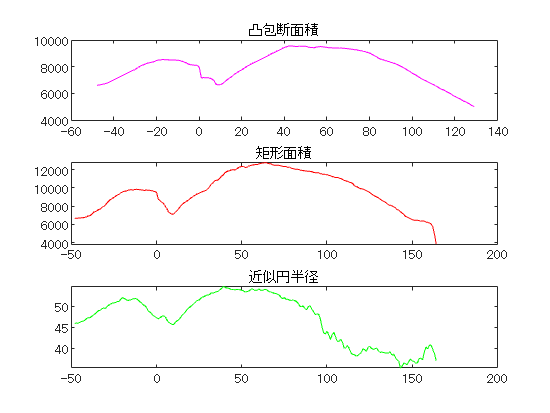

avPos = ConvArea(:,1); 
avarea = ConvArea(:,3);
recPos = rectangleArea(:,1);
recArea = rectangleArea(:,3);
fitPos = FitCircleRho(:,1);
fitCirRho = FitCircleRho(:,3);

plavPos = avPos(idx_av);
plavarea = avarea(idx_av);
plrecPos = recPos(idx_rec);
plrecArea = recArea(idx_rec);
plfitPos = fitPos(idx_rho);
plfitCirRho = fitCirRho(idx_rho);



num = length(avPos);
zer = zeros(num, 1);
figure("Name", 'subplot')
subplot(3,1,1)
% plot(avPos, avarea, 'm');
plot(plavPos, plavarea, 'm');
title("凸包断面積")

subplot(3,1,2)
% plot(recPos, recArea, 'r');
plot(plrecPos, plrecArea, 'r');
title("矩形面積")

subplot(3,1,3)
% plot(fitPos, fitCirRho, 'g');
plot(plfitPos, plfitCirRho, 'g');
title("近似円半径")

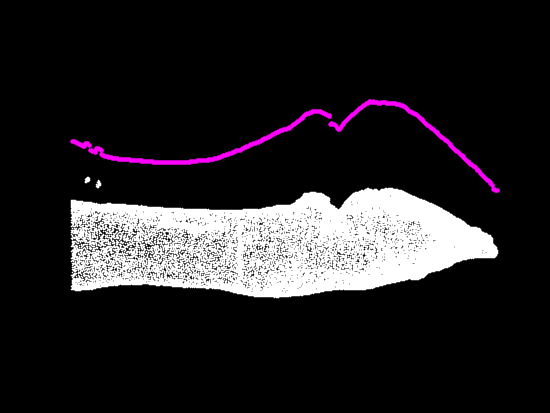


viewav = [ConvArea(:,1)  ConvArea(:,2) ConvArea(:,3)/100+50];
viewrec = [rectangleArea(:,1) rectangleArea(:,2) rectangleArea(:,3)/100];
viewrho = [FitCircleRho(:,1) FitCircleRho(:,2) FitCircleRho(:,3)*1.2];

markSize = 70;
figure("Name","All-Data_PLOT")
pcshow(viewav, 'm', "MarkerSize", markSize);
hold on;
% pcshow(viewrec, 'r', "MarkerSize", markSize);
% pcshow(viewrho, 'g',"MarkerSize", markSize);

xli = ptCloud.XLimits;
x_range = abs(xli(2)-xli(1));

gridStep = 0.1;
% ptCloudA = pcdownsample(ptCloud,'gridAverage',gridStep);
% ptCloudA = pcdownsample(ptCloud, "random", 0.2, PreserveStructure=true);

pcshow(sp,'w', "MarkerSize", 4, "Projection", "orthographic")
% pcshow(sp,"MarkerSize", 4, "Projection", "orthographic")

view([0 0]);
hold off

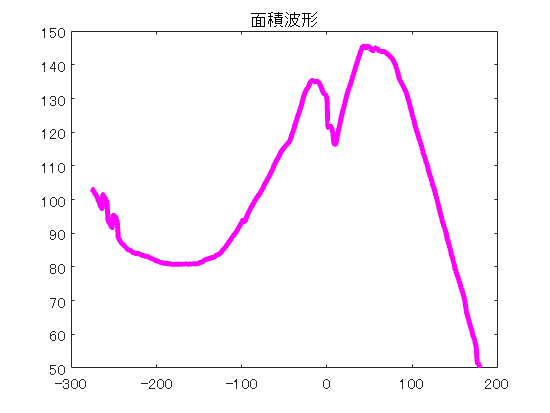


figure;
plot(viewav(:,1), viewav(:,3), 'm','LineWidth',3);
title('面積波形')

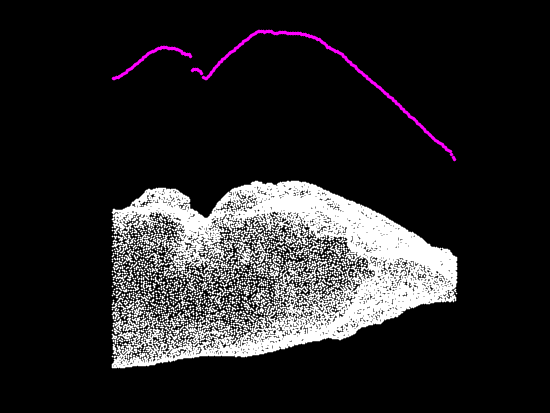

markSize = 50;
m1 = max(viewav(:,1));
m2 = max(viewrec(:,1));
m3 = max(viewrho(:,1));
figure("Name","Plus-Data_PLOT")
pcshow(viewav(viewav(:,1)>=center & m1 - 15 > viewav(:,1),:), 'm', "MarkerSize", 40);
hold on;
% pcshow(viewrec(viewrec(:,1)>=center & m2 - 15 > viewrec(:,1),:), 'r', "MarkerSize", markSize);
% pcshow(viewrho(viewrho(:,1)>=center & m3 - 15 > viewrho(:,1),:), 'g',"MarkerSize", markSize);
sp_c = sp(sp(:,1) >= center & psx_max-15 > sp(:,1),:);

pcshow(sp_c, 'w', "MarkerSize", 4, "Projection", "orthographic")
view([0 0]);
hold off;

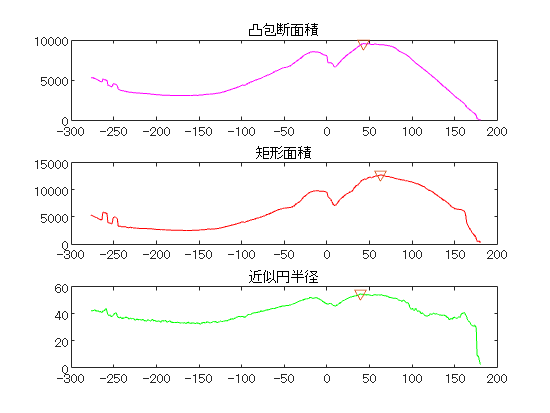

[cMax, c_idx] = max(ConvArea(:,3));
[rhMax, rh_idx] = max(FitCircleRho(:,3));
[recMax, rec_idx] = max(rectangleArea(:,3));

figure("Name", 'subplot')
subplot(3,1,1)
plot(avPos, avarea,'m', avPos(c_idx),avarea(c_idx),'v');
title("凸包断面積")

subplot(3,1,2)
plot(recPos, recArea,'r', recPos(rec_idx),recArea(rec_idx),'v');
title("矩形面積")

subplot(3,1,3)
plot(fitPos, fitCirRho,'g',fitPos(rh_idx),fitCirRho(rh_idx), 'v');
title("近似円半径")

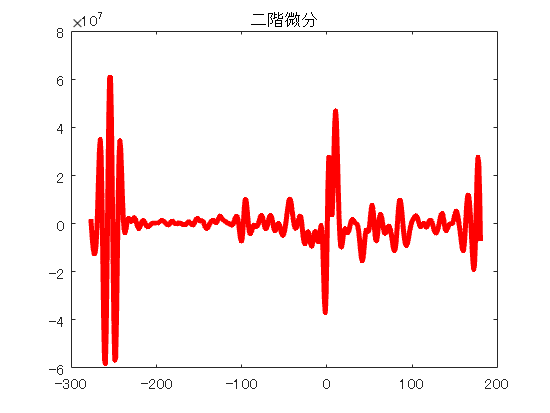

n = 3;
Wn = 0.2;

[av_y, a_v1, a_v2] = filterAnddiff(plavarea, n, Wn);
[aa, aa_v1, aa_v2] = filterAnddiff(avarea, n, Wn);
figure("Name", 'find kubire')
plot(avPos, aa_v2, 'r','LineWidth',3)
title("二階微分")

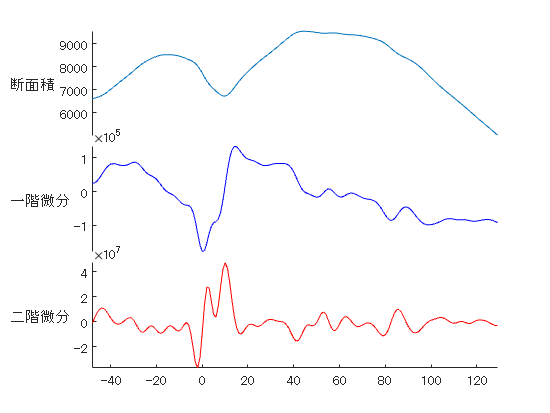

figure;
newLabels = ["断面積", "一階微分", "二階微分"];
s = stackedplot(plavPos, [av_y, a_v1, a_v2], 'DisplayLabels',newLabels, 'Color','r');
s.LineProperties(1).Color = '#0072BD';
s.LineProperties(2).Color = 'b';
s.LineProperties(3).Color = 'r';

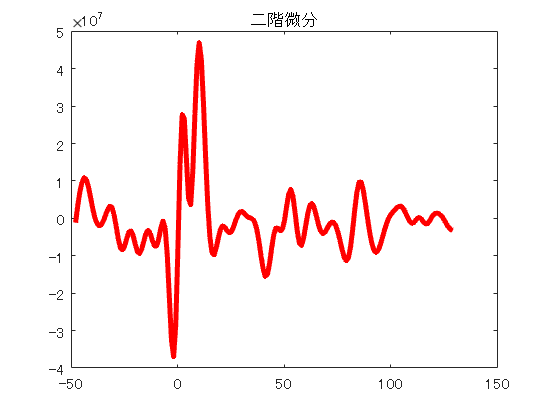

TF = islocalmin(a_v1, 'MaxNumExtrema',1 );
TF2 = islocalmax(a_v2, 'MaxNumExtrema',1);

figure("Name", 'find kubire')
% subplot(2,1,1)
% % plot(avPos, avarea, 'm');
% plot(plavPos, plavarea, 'm');
% title("凸包断面積")

% subplot(2,1,2)
% plot(recPos, recArea, 'r');
% plot(plavPos, a_v2, 'r','LineWidth',5 ,plavPos(TF2), a_v2(TF2), 'o');
plot(plavPos, a_v2, 'r','LineWidth',3)
title("二階微分")


sec2At = plavPos(TF2)

sec2At =   10.040847402006364


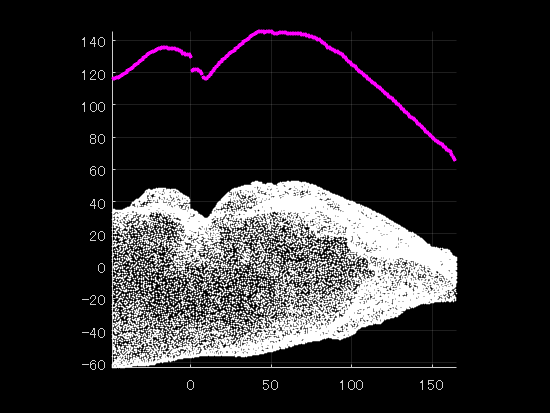

figure("Name","Plus-Data_PLOT")
pcshow(viewav(viewav(:,1)>=center & m1 - 15 > viewav(:,1),:), 'm', "MarkerSize", markSize);
hold on;
% pcshow(viewrec(viewrec(:,1)>=center & m2 - 15 > viewrec(:,1),:), 'r', "MarkerSize", markSize);
% pcshow(viewrho(viewrho(:,1)>=center & m3 - 15 > viewrho(:,1),:), 'g',"MarkerSize", markSize);
sp_c = sp(sp(:,1) >= center & psx_max-15 > sp(:,1),:);

pcshow(sp_c,'w', "AxesVisibility", "on", "MarkerSize", 4, "Projection", "orthographic")
view([0 0]);
hold off;

idx_sec2 = avPos < sec2At & sec2At-70 < avPos;

sec2avPos = avPos(idx_sec2);
sec2avArea = avarea(idx_sec2);

[s2av_y, s2a_v1, s2a_v2] = filterAnddiff(sec2avArea, n, Wn);
s2_TF2 = islocalmax(s2a_v2, 'MaxNumExtrema',1);
[max_s2y, I_sec2] = max(s2av_y)

max_s2y =      8.530544351147320e+03


I_sec2 =     44


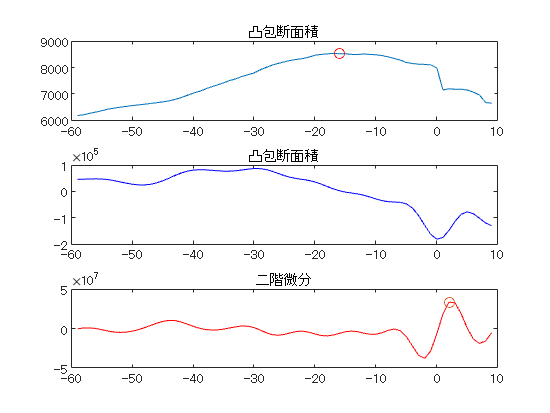


figure("Name", 'subplot')
subplot(3,1,1)
plot(sec2avPos, sec2avArea, sec2avPos(I_sec2), sec2avArea(I_sec2), 'or');
title("凸包断面積")

subplot(3,1,2)
plot(sec2avPos, s2a_v1, 'b');
title("凸包断面積")
subplot(3,1,3)
plot(sec2avPos, s2a_v2, 'r', sec2avPos(s2_TF2), s2a_v2(s2_TF2), 'o');
title("二階微分")

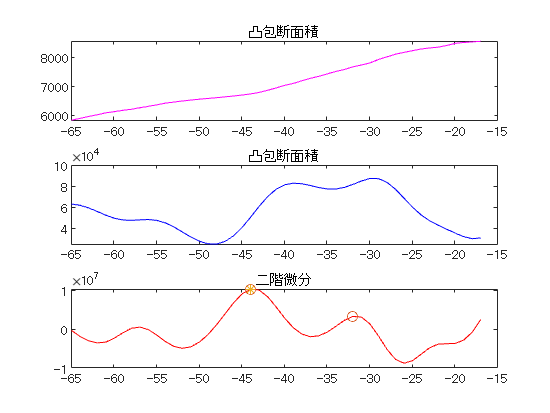

sec3At = sec2avPos(I_sec2);
idx_sec3 = avPos < sec3At & sec3At-50 < avPos;

sec3avPos = avPos(idx_sec3);
sec3avArea = avarea(idx_sec3);
[s3av_y, s3a_v1, s3a_v2]= filterAnddiff(sec3avArea, n, Wn);
s3_TF = islocalmax(s3a_v1, 'MaxNumExtrema',1);
s3_TF2 = islocalmax(s3a_v2, 'MaxNumExtrema',2);
[m3, I_sec3] = max(s3_TF2);
figure("Name", 'subplot')
subplot(3,1,1)
plot(sec3avPos, sec3avArea, 'm');
title("凸包断面積")

subplot(3,1,2)
plot(sec3avPos, s3a_v1, 'b');
title("凸包断面積")

subplot(3,1,3)
plot(sec3avPos, s3a_v2, 'r', sec3avPos(s3_TF2), s3a_v2(s3_TF2), 'o', sec3avPos(I_sec3), s3a_v2(I_sec3), '*');
title("二階微分")


CircumCenter = sec3avPos(I_sec3);

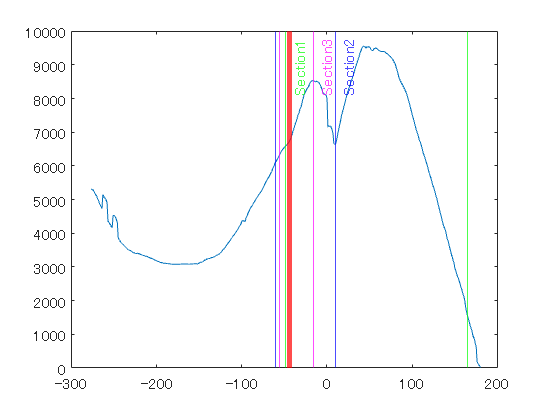

sec2At;
sec3At;
sec1At = center;
sec2_xline = sec2At;
sec3_xline = sec3At;
sec1_max = max(avPos)-15;

x_line = repmat(CircumCenter,200, 1);
z_line = linspace(-100, 125, 200)';
y_line = zeros(200, 1);
y_line2 = zeros(length(avPos), 1);
pc_line = [x_line y_line z_line];
pc_conv = [avPos y_line2 avarea/100];
sfig1 = figure("Name", "Show_Section");
plot(avPos, avarea);
xline(sec1At, '-g', {'Section1'});
xline(sec1_max, '-g')
xline(sec2_xline, '-b',{'Section2'});
xline(sec2_xline-70,'-b');
xline(sec3_xline, '-m',{'Section3'});
xline(sec3_xline-40, '-m');
xline(CircumCenter, '-r', 'LineWidth',3);



viewav = [ConvArea(:,1)  ConvArea(:,2) ConvArea(:,3)/100+30];
[Y, aV1, aV2] = filterAnddiff(ConvArea(:,3)/100, n, Wn);
pt = ptCloud.Location;

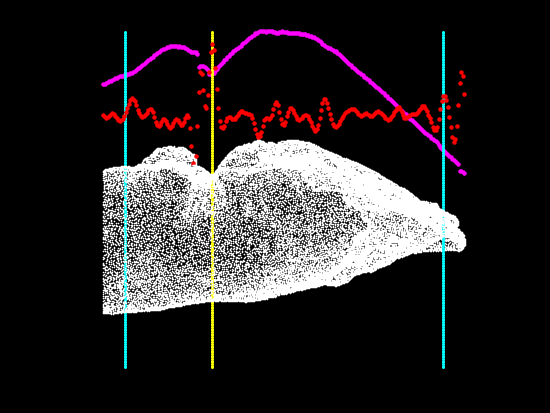

MarkerSize = 70;
sectionLine = 30;
diff1_pc = [ConvArea(:,1) ConvArea(:,2), (aV1/100)+70];
diff2_pc = [ConvArea(:,1) ConvArea(:,2), (aV2/10000)+70];
figure("Name", "Focus Kubire(Section 1)")
pcshow(viewav(viewav(:,1)>=center-15 & m1 > viewav(:,1),:), 'm', "MarkerSize", MarkerSize);
hold on;
sp_c = sp(sp(:,1) >= center-15 & psx_max > sp(:,1),:);
sec1At_pc = [repmat(sec1At,200, 1) y_line, z_line];
sec1end_pc = [repmat(m1-15,200, 1) y_line, z_line];
sec2_at_pc = [repmat(sec2At, 200, 1) y_line z_line];
pcshow(sec1At_pc, 'c', "MarkerSize", sectionLine);
pcshow(sec1end_pc, 'c' ,"MarkerSize", sectionLine);
pcshow(sec2_at_pc, 'y', 'MarkerSize', sectionLine);
d2_sec2 = diff2_pc(diff2_pc(:,1) >= center-15 & psx_max > diff2_pc(:,1), :);
pcshow(d2_sec2, 'r', 'MarkerSize', MarkerSize);
% pcshow(sp_c,'w', "AxesVisibility", "on", "MarkerSize", 4, "Projection", "orthographic")
pcshow(sp_c, 'w', "MarkerSize", 4, "Projection", "orthographic")
view([0 0]);
hold off;

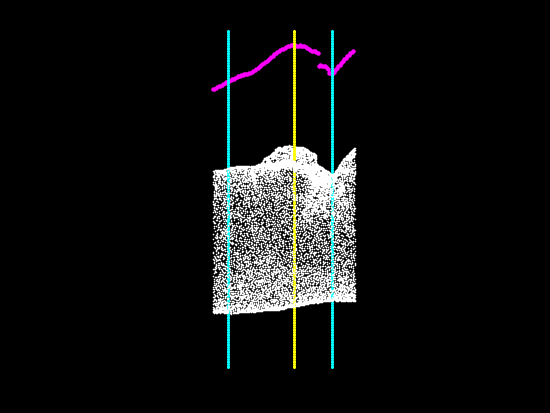

figure("Name", "Section2")
pcshow(viewav(viewav(:,1)>=sec2At-80 & sec2At+15 > viewav(:,1),:), 'm', "MarkerSize", MarkerSize);
hold on;
sec2At_pc = [repmat(sec2At,200, 1) y_line, z_line];
sec2end_pc = [repmat(sec2At-70,200, 1) y_line, z_line];
sec3At_pc = [repmat(sec3At,200, 1) y_line, z_line];
sp_sec2 = sp(sp(:,1) < sec2At+15 & sec2At-80 <= sp(:,1), :);
pcshow(sec2At_pc, 'c', "MarkerSize", sectionLine);
pcshow(sec2end_pc, 'c' ,"MarkerSize", sectionLine);
pcshow(sec3At_pc, 'y', "MarkerSize", sectionLine);
% pcshow(sp_sec2, 'w', "Projection", "orthographic");
pcshow(sp_sec2, 'w',"Projection", "orthographic");
view([0 0])
hold off;

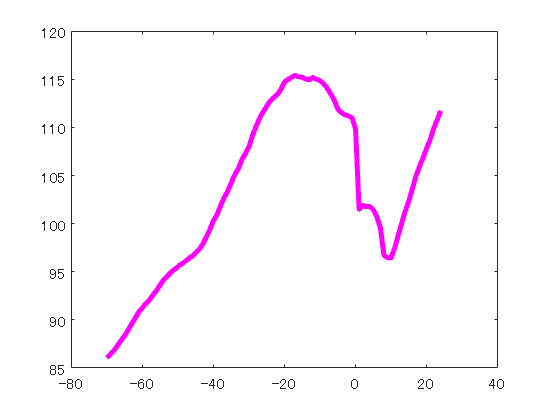

vv2 = viewav(viewav(:,1)>=sec2At-80 & sec2At+15 > viewav(:,1),:);
figure("Name", 'sec2')
plot(vv2(:,1), vv2(:,3), 'Color','m', 'LineWidth',3);

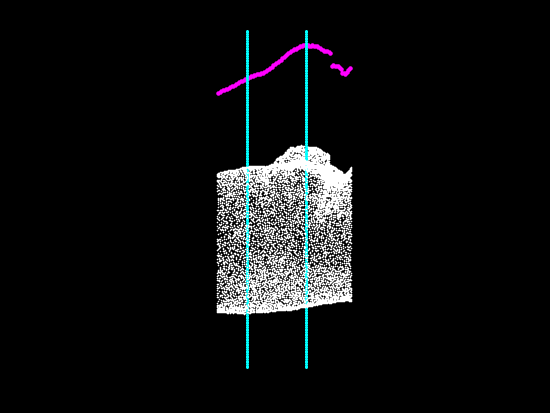



figure("Name","Focus at hukutei");
sec3At = sec2avPos(I_sec2);
idx_sec3 = avPos < sec3At & sec3At-50 < avPos;
sp_sec3 = sp(sp(:,1) < sec3At+30 & sec3At-60 < sp(:,1), :);
% sec3At_pc = [repmat(sec3At,200, 1) y_line, z_line];
sec3end_pc = [repmat(sec3At-40,200, 1) y_line, z_line];
pcshow(viewav(viewav(:,1) < sec3At+30 &  sec3At-60  < viewav(:,1),:), 'm', "MarkerSize", MarkerSize);
hold on;
pcshow(sec3At_pc, 'c', "MarkerSize", sectionLine);
pcshow(sec3end_pc, 'c' ,"MarkerSize", sectionLine);
% pcshow(sp_sec3, 'w', "Projection", "orthographic");
pcshow(sp_sec3,'w', "Projection", "orthographic");
view([0 0])
hold off;

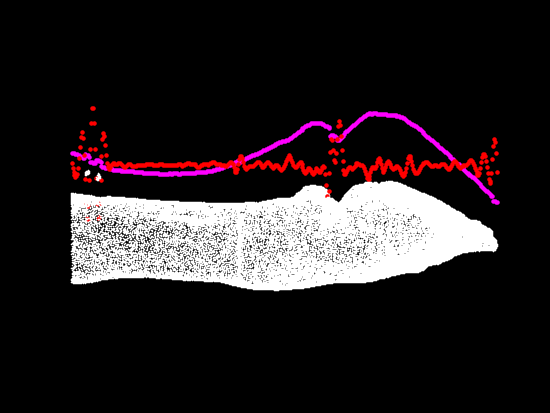



sfig2 = figure("Name","GETFIG");
pcshow(viewav, 'm', 'MarkerSize', MarkerSize);
hold on;
% pcshow(pc_line, 'g', 'MarkerSize', 25);
% pcshow(diff1_pc, 'b','MarkerSize', MarkerSize)
pcshow(diff2_pc, 'r','MarkerSize', MarkerSize)
% pcshow(pt, 'w', 'AxesVisibility', 'on', 'MarkerSize', 12);
pcshow(sp,'w', 'Projection', 'orthographic');
view([0 0])
hold off

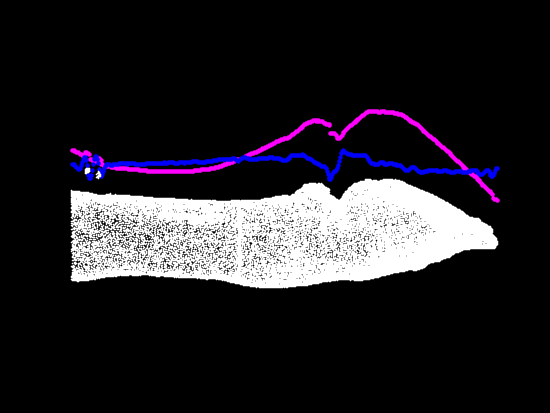


figure;
pcshow(viewav, 'm', 'MarkerSize', MarkerSize);
hold on;
pcshow(diff1_pc, 'b','MarkerSize', MarkerSize)
% pcshow(diff2_pc, 'r','MarkerSize', MarkerSize)
% pcshow(pt, 'w', 'AxesVisibility', 'on', 'MarkerSize', 12);
pcshow(sp,'w', 'Projection', 'orthographic');
view([0 0])
hold off

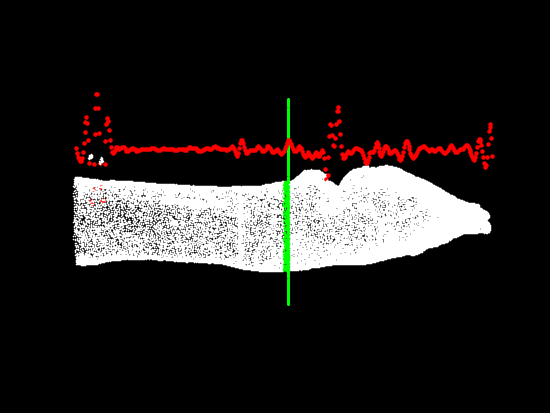

sampleWidth = 5;
getCase1 = [CircumCenter, CircumCenter-sampleWidth];
getCase2 = [CircumCenter-sampleWidth, CircumCenter-sampleWidth*2];

idx1 = PosData >= getCase1(2) & getCase1(1) >= PosData;
idx2 = PosData >= getCase2(2) & getCase2(1) >= PosData;
getPoint1 = PointSet(idx1);
getPoint2 = PointSet(idx2);
getPoint1(1);

sfig3 = figure('Name', 'marking');
hold on;
pcshow(sp, 'w', 'AxesVisibility', 'on');
pcshow(pc_line, 'r')
leng1 = zeros(length(getPoint1), 1);
leng2 =  zeros(length(getPoint2), 1);
% at1 = onews(length())
atCir1 = [];
atCir2 = [];
for i = 1:length(getPoint1)
    gp = getPoint1(i).Location;
    gp_c= [gp(:,2) gp(:,3)];
    [thetaSorted, rhoSorted] = sortPointOnPolar(gp_c);
    [gp_x, gp_y] = pol2cart(thetaSorted, rhoSorted);
    gp_cross = [gp_x gp_y];
    try
        k = convhull(gp_cross);
    catch
        continue;
    end
    gpk = [gp_cross(k, 1), gp_cross(k,2)];
%     figure(i);
%     plot(gpk(:,1), gpk(:,2), '-or');
    len = calculateLengthForPoint(gpk);
    leng1(i) = len; 
    pcshow(gp, 'g', AxesVisibility="on");
   
    at1 = atCir1;
    atCir1 = [at1; gp];
end

for i = 1:length(getPoint2)
    gp = getPoint2(i).Location;
    gp_c= [gp(:,2) gp(:,3)];
    [thetaSorted, rhoSorted] = sortPointOnPolar(gp_c);
    [gp_x, gp_y] = pol2cart(thetaSorted, rhoSorted);
    gp_cross = [gp_x gp_y];
    try
        k = convhull(gp_cross);
    catch
        continue;
    end
    gpk = [gp_cross(k, 1), gp_cross(k,2)];
%     figure(i);
%     plot(gpk(:,1), gpk(:,2), '-or');
    len = calculateLengthForPoint(gpk);
    leng2(i) = len; 
%     pcshow(gp, 'b', AxesVisibility="on");
    at2 = atCir2;
    atCir2 = [at2; gp];
end
pcshow(pc_line, 'g', 'MarkerSize', sectionLine);
% pcshow(diff1_pc, 'b','MarkerSize', MarkerSize)
pcshow(diff2_pc, 'r','MarkerSize', MarkerSize)
% pcshow(sp,  'AxesVisibility', 'on');
view([0 0])
hold off
hold off;

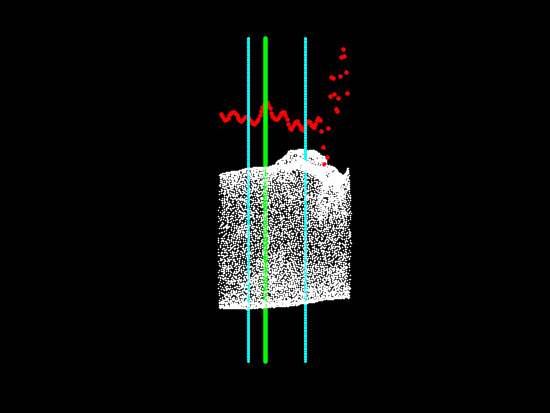

figure("Name","Focus at hukutei");
sec3At = sec2avPos(I_sec2);
idx_sec3 = avPos < sec3At & sec3At-50 < avPos;
sp_sec3 = sp(sp(:,1) < sec3At+30 & sec3At-60 < sp(:,1), :);
diff2_pc_sec3 = diff2_pc(diff2_pc(:,1) < sec3At+30 &sec3At-60< diff2_pc(:,1), : );
diff2_pc_sec3_2 = diff2_pc(diff2_pc(:,1) < sec3At &sec3At-40< diff2_pc(:,1), : );
% sec3At_pc = [repmat(sec3At,200, 1) y_line, z_line];

sec3end_pc = [repmat(sec3At-40,200, 1) y_line, z_line];
% pcshow(viewav(viewav(:,1) < sec3At+30 &  sec3At-60  < viewav(:,1),:), 'm', "MarkerSize", MarkerSize);
pcshow(diff2_pc_sec3, 'r', 'MarkerSize', MarkerSize);
hold on;
pcshow(diff2_pc_sec3, 'r', 'MarkerSize', MarkerSize);
pcshow(sec3At_pc, 'c', "MarkerSize", sectionLine);
pcshow(sec3end_pc, 'c' ,"MarkerSize", sectionLine);
% pcshow(sp_sec3, 'w', "Projection", "orthographic");
pcshow(sp_sec3,'w', "Projection", "orthographic");
pcshow(pc_line, 'g', 'MarkerSize', MarkerSize);
view([0 0])
hold off;

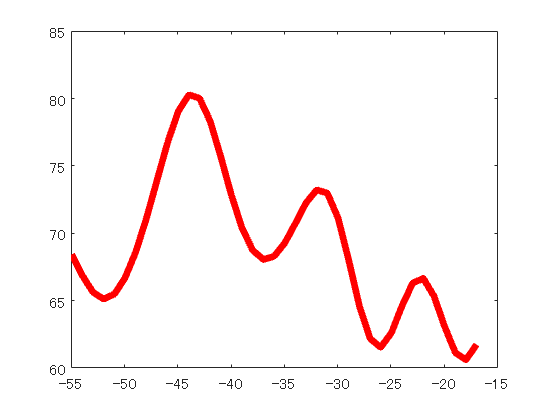


figure;
plot(diff2_pc_sec3_2(:,1), diff2_pc_sec3_2(:,3), 'Color','r', 'LineWidth', 4);
hold on;
% plot(sec3avPos(I_sec3), s3a_v2(I_sec3), 'o');
hold off;

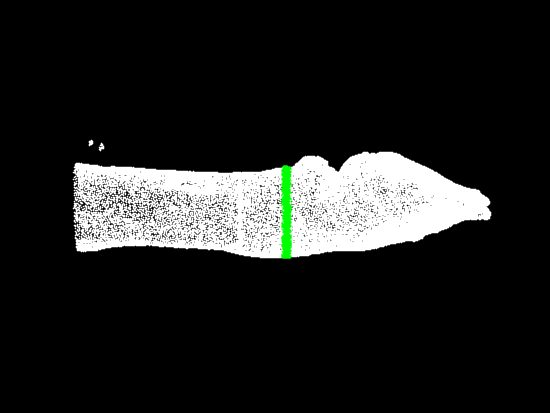

figure;
pcshow(sp, 'w');
hold on;

pcshow(atCir1, 'g', 'MarkerSize', MarkerSize);
% pcshow(pc_line, 'g', 'MarkerSize', 25);
% pcshow(atCir2, 'b', 'AxesVisibility', 'on');
view([0 0])
hold off;

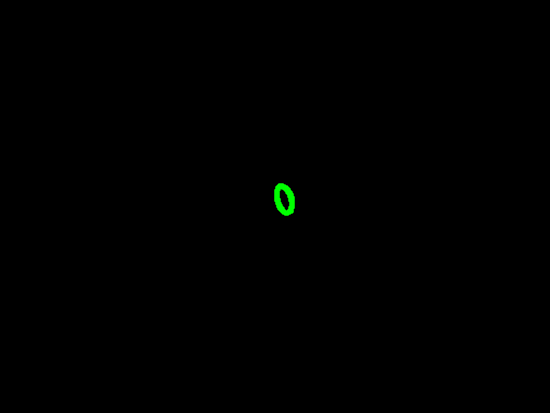

figure;
hold on;
pcshow(atCir1, 'g', 'MarkerSize', MarkerSize);

% pcshow(sp)
Circum1 = mean(leng1)

Circum1 =      2.910837126781187e+02


Circum2 = mean(leng2)

Circum2 =      2.879073343437624e+02


hl1 = predictHoofBackWall(Circum1)

hl1 =   85.923290209368602


hl2 = predictHoofBackWall(Circum2)

hl2 =   85.377270773692757


saveMat = [string(file), Circum1, Circum2, hl1, hl2];
savename = 'newMethod_re';
ext = '.xlsx';
savexlsx = append(savename, ext);
writematrix(saveMat, savexlsx, 'WriteMode','append');

path = 'redo/Third3dfile/'; % macは/windowsは\
path2 = 'redo/ThirdnumData/';
chfile = convertStringsToChars(file);
idx_f = length(chfile);
nfile = chfile(1:idx_f-4);
newfile = [path, nfile, '.mat']

newfile = 'redo/Third3dfile/Busako_RH_0000_2.mat'

newfile2 = [path2, nfile, '_data_', '.mat'];
nPoint = ptCloud;
renPoint = ptCloudA;

関数または変数 'ptCloudA' が認識されません。

Circum1Pt = pointCloud(atCir1);
Circum2Pt = pointCloud(atCir2);
numData = [Circum1, Circum2, hl1, hl2]
save(newfile, 'nPoint', 'renPoint','Circum1Pt','Circum2Pt','-mat');
save(newfile2, 'Circum1', 'Circum2', 'hl1', 'hl2', '-mat')
figpath = 'redo/newfig/';
figfile1 = [figpath, nfile,'_Section', '.fig'];
savefig(sfig1, figfile1);
figpath2 = 'redo/modelfig/'
figfile2 = [figpath2, nfile,'_Section_model', '.fig'];
savefig(sfig2, figfile2);
figpath3 = 'redo/markfig/';
figfile3 = [figpath3, nfile,'_Section_mark_', '.fig'];
savefig(sfig3, figfile3);